# 14주차 과제 — 관측기와 분리원리

**제어시스템설계** · 충남대학교 자율운항시스템공학과

문제는 **세 개**입니다.

- **1. 몸풀기** (쉬움 · 수업 중 10분 · 30점) — 관측기 이득 $L$ 구하기

- **2. 기본** (중간 · 40분 · 70점) — 분리원리 확인과 관측기 속도 고르기

- **3. 도전** (선택 · 가산점 10점) — 잡음이 있을 때의 맞바꿈

**3번은 선택입니다.** 1번과 2번만 해도 만점입니다.

clc; close all;
s = tf('s');

## 1. 몸풀기 — 관측기 이득 L 구하기

**강의노트 3절을 그대로 보면 됩니다.**

아래 시스템에서 $A - LC$ 의 고유값을 $-6$ 과 $-8$ 에 놓는 $L$ 을 구하십시오.


$$A = \left[\begin{array}{cc} 0 & 1\\ -2 & -3\end{array}\right], \qquad C = \left[\begin{array}{cc} 1 & 0\end{array}\right]$$


힌트 — 전치 트릭입니다. `place(A', C', p)'` 에서 **작은따옴표 위치**에 주의하십시오.

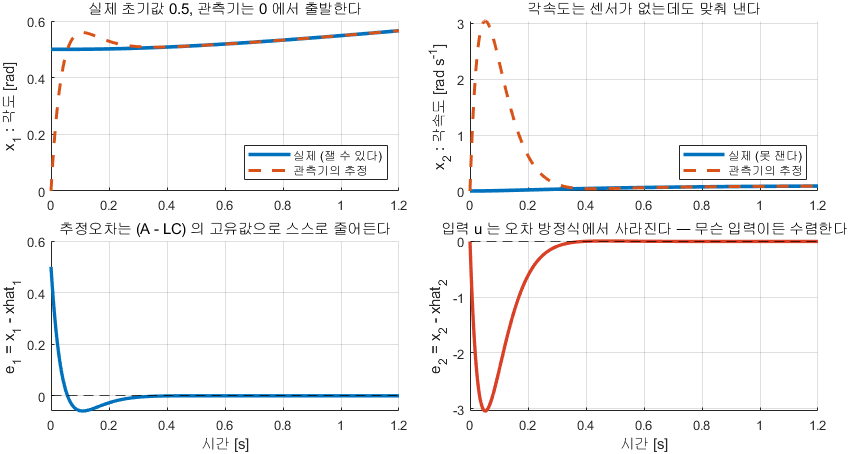

관측기는 0 에서 출발해도 따라잡는다

**그림 파일** `w14_converge.png` — `make_figures.m` 의 `fig_obs_converge` · 다시 만들려면 `make_figures('w14_converge')`

## 1-1. L 구하기

`TODO` 한 줄만 채우면 됩니다.

A1 = [0 1; -2 -3];
C1 = [1 0];

L1 = NaN;
% TODO : L1 = place(A1', C1', [-6 -8])';   로 바꾸십시오

if isnan(L1)
    fprintf('  (아직 안 채웠습니다)\n');
else
    fprintf('  L = %s   (열벡터여야 합니다)\n', mat2str(round(L1.', 4)));
    fprintf('  검증 eig(A - L*C) = %s\n', ...
            mat2str(round(sort(eig(A1 - L1*C1)).', 4)));
end

## 1-2. 답할 것 (세 문장이면 됩니다)

- 관측기를 만들기 전에 무엇을 먼저 확인해야 합니까? 이 시스템은 만족합니까?

- 왜 `place(A, C, p)` 가 아니라 `place(A', C', p)'` 입니까?

- $L$ 이 커지면 관측기가 무엇을 더 세게 믿는 것입니까?

## 2. 기본 — 분리원리와 관측기 속도

**강의노트 5~8절을 보면 됩니다.**

DC 모터 위치제어에서 제어기 극을 $[-8\;\;-10\;\;-12]$ 로 고정하고, 관측기 극을 그 **몇 배**로 잡을지 정합니다.

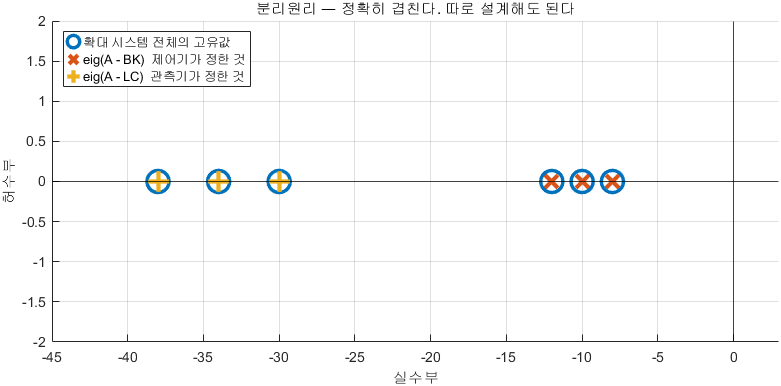

분리원리 — 정확히 겹친다

**그림 파일** `w14_separation.png` — `make_figures.m` 의 `fig_separation` · 다시 만들려면 `make_figures('w14_separation')`

[Gp, p] = plant_dcmotor('position');
A = p.A;  B = p.B;  C = p.C;  D = p.D;
n = size(A,1);
p_ctrl = [-8 -10 -12];
K = place(A, B, p_ctrl);

## 2-1. 분리원리 확인하기

`TODO` 두 줄만 채우면 됩니다.

L = place(A', C', 3*p_ctrl)';

Aaug = NaN;
% TODO : Aaug = [A, -B*K; L*C, A - B*K - L*C];   로 바꾸십시오

if isnan(Aaug)
    fprintf('\n  (아직 안 채웠습니다)\n');
else
    e_aug = sort(eig(Aaug));
    e_two = NaN;
    % TODO : e_two = sort([eig(A - B*K); eig(A - L*C)]);   로 바꾸십시오

    fprintf('\n  확대 시스템 고유값 : %s\n', mat2str(round(e_aug.', 2)));
    if ~isnan(e_two)
        fprintf('  eig(A-BK) 와 eig(A-LC) 를 합친 것 : %s\n', ...
                mat2str(round(e_two.', 2)));
        fprintf('  최대 차이 : %.2e\n', max(abs(e_aug - e_two)));
    end
end

## 2-2. 관측기 속도 고르기

**이 절은 코드가 다 되어 있습니다.** 실행하고 표를 읽으십시오.

실제 플랜트는 $x(0) = [0.3;\;0;\;0]$ 에서 출발하고, 관측기는 $0$ 에서 출발합니다 (아무것도 모릅니다).

t = (0:0.001:1.5)';
r = ones(size(t));
Kr = 1/dcgain(ss(A - B*K, B, C, D));

fprintf('\n     배수      |L|     정착시간[s]   초기 오버슈트[%%]\n');
fprintf('   -------  ---------  ------------  ----------------\n');
mults = [1 2 3 5];
Y = zeros(numel(t), numel(mults));
for j = 1:numel(mults)
    Lj = place(A', C', mults(j)*p_ctrl)';
    Aj = [A, -B*K; Lj*C, A - B*K - Lj*C];
    Sj = ss(Aj, [B*Kr; B*Kr], [C, zeros(1,n)], 0);
    Y(:,j) = lsim(Sj, r, t, [0.3; 0; 0; 0; 0; 0]);
    si = stepinfo(Y(:,j), t, 1);
    fprintf('   %7d  %9.0f  %12.3f  %16.1f\n', ...
            mults(j), norm(Lj), si.SettlingTime, si.Overshoot);
end

hold on; grid on;
for j = 1:numel(mults)
    plot(t, Y(:,j), 'LineWidth', 2.2, ...
         'DisplayName', sprintf('관측기 극 = 제어기 극의 %d 배', mults(j)));
end
yline(1, 'k--', 'HandleVisibility','off');
xlabel('시간 [s]'); ylabel('각도 [rad]');
legend('Location','southeast');
title('관측기가 느리면 초반이 흔들린다');

## 2-3. 답할 것 (네 문장이면 됩니다)

- 확대 시스템의 고유값이 두 목록을 합친 것과 같습니까? 그것을 무엇이라 부릅니까?

- 분리원리가 **없었다면** 설계가 어떻게 달라졌을지 한 문장으로 쓰십시오

- 위 표에서 $1$ 배 관측기는 왜 나쁩니까? 그림에서 무엇이 보입니까?

- 그럼 배수를 무한히 키우면 됩니까? 안 된다면 왜 안 됩니까?

## 3. 도전 (선택) — 잡음이 있을 때

**강의노트 6절을 보면 됩니다.** 안 해도 감점 없습니다.

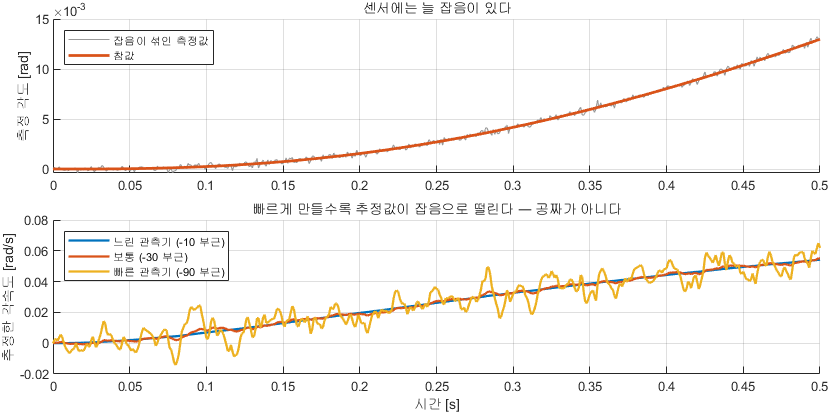

빠르게 만들수록 추정값이 잡음으로 떨린다

**그림 파일** `w14_obs_noise.png` — `make_figures.m` 의 `fig_obs_noise` · 다시 만들려면 `make_figures('w14_obs_noise')`

할 일

- 측정 각도에 표준편차 $3\times 10^{-4}$ rad 의 잡음을 섞으십시오 (`noise = 3e-4*randn(size(t));`)

- 관측기를 $1$ 배, $3$ 배, $9$ 배로 만들어 추정 각속도를 그리십시오

- 각 경우의 **추정 각속도가 참값에서 얼마나 떠는지** 표준편차로 재십시오

- **가장 중요한 질문** — 2-2 절의 표(빠를수록 좋다)와 이 절의 결과(빠를수록 나쁘다)를 함께 보면, 배수를 어떻게 정해야 합니까?

힌트 — 관측기만 따로 돌리려면 이렇게 하면 됩니다.

`obs = ss(A - L*C, [B, L], eye(n), zeros(n,2));` `Xh  = lsim(obs, [u, y_meas], t, zeros(n,1));`

fprintf('\n=== 3. 도전 문제 ===\n');
fprintf('  (여기서부터 직접 해 보십시오)\n');

## 4. 제출 방법

- 이 파일을 `W14_HW_학번_이름.mlx` 로 저장해 제출하십시오

- `TODO` 를 채운 코드와 **실행 결과(그림 포함)** 가 함께 보여야 합니다

- 답할 것은 각 문제 아래에 **글로 적으십시오**. 한두 문장이면 충분합니다

- 도전 문제를 안 했으면 그 절은 그대로 두십시오

## 5. 채점 기준

- **1. 몸풀기** 30점 — $L$ 을 구했는가, 세 질문에 답했는가

- **2. 기본** 70점 — 분리원리를 확인했는가, 표를 읽었는가, 네 질문에 답했는가

- **3. 도전** 가산점 10점 — 잡음 실험을 하고 배수를 어떻게 정할지 썼는가

감점 항목 (세 개뿐입니다)

- `place(A'', C'', p)` 에서 **마지막 전치를 빼먹은 경우**

- $L$ 을 크게 잡을수록 좋다고 결론 내린 경우 (잡음을 봐야 합니다)

- 그림에 축 이름이나 범례가 없는 경우